close;
clear;
clc;

# 0. parameters

global alpha beta c_0 c_e z_bar sigma rho D_bar w lambda N grid_z  ...
       G_z prob_z
    

alpha = 0.7;
beta = 0.96;
c_0 = 8;
c_e = 6;
z_bar = 1;
sigma = 0.2;
rho = 0.5;
D_bar = 100;
w = 1;
lambda = 0.3;
N = 101;
[grid_z, prob_z] = tauchen(N,z_bar,rho,sigma,4);
grid_z = exp(grid_z);
G_z = (ones(N,1)/N);
G_z = (G_z'*(prob_z)^1000)';


## 1. eqm price

labor_demand = @(p,z) (alpha*z*p).^(1/(1-alpha));
p_eqm = bisect(@solve_p,0.001,10);
V = zeros(N,1);
tol = 1e-6;
crit = 1;
maxit = 1000;
V_new = zeros(N,1);
for iter = 1:maxit
    V_new = p_eqm*grid_z.*labor_demand(p_eqm,grid_z).^alpha-w*(labor_demand(p_eqm,grid_z)+c_0)+...
        beta*max(prob_z*V,0);
    
    crit = max(abs(V_new-V),[],"all");
    V = lambda*V_new + (1-lambda)*V;
    if crit<tol
        break
    end
end
id_ztilde = find(prob_z*V >=0 ,1, 'first')

id_ztilde = 37

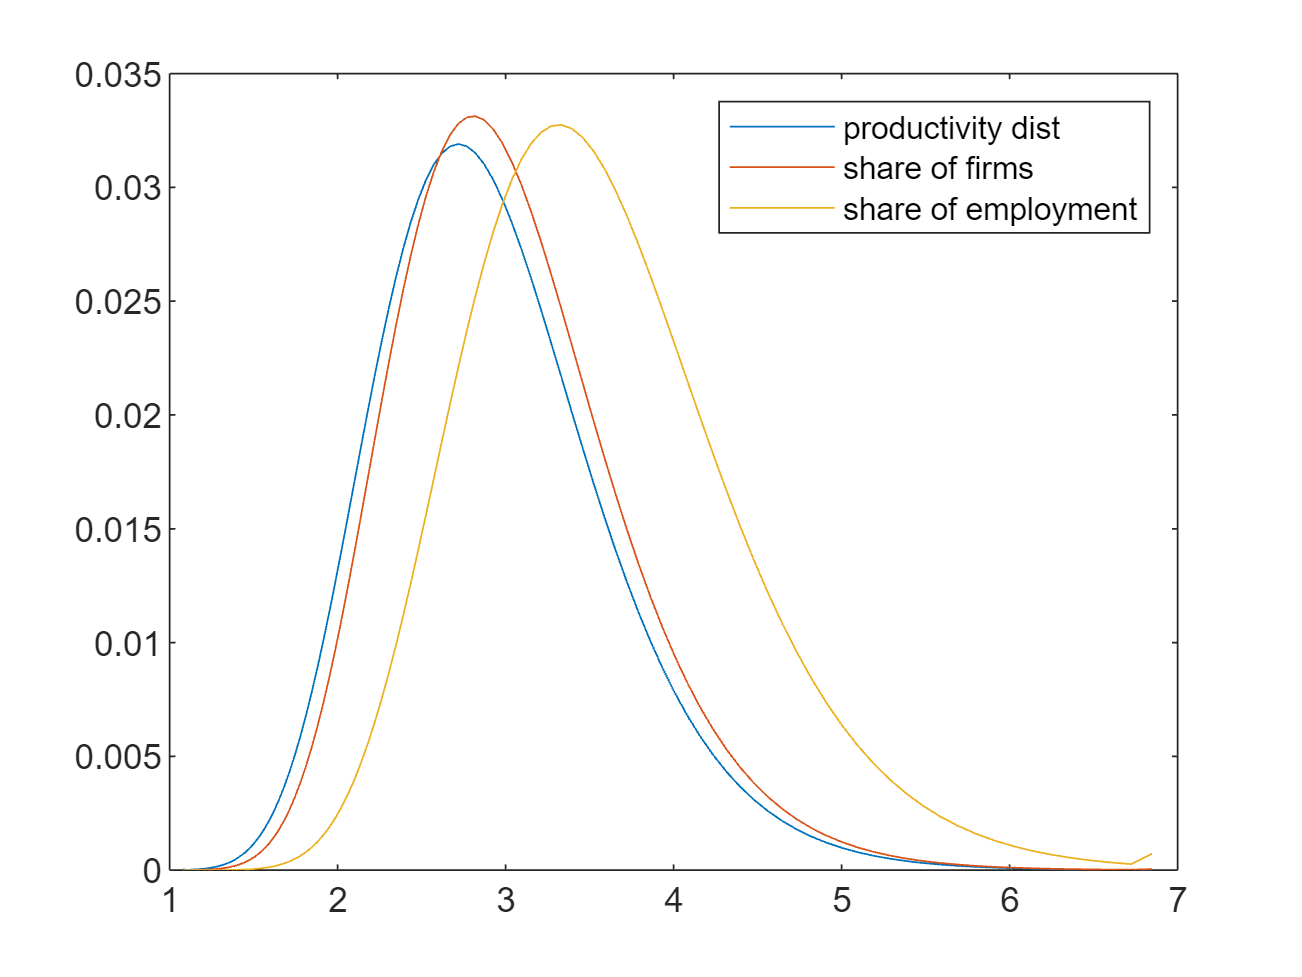

ztilde = grid_z(id_ztilde);
exit_rule = [ones(id_ztilde,1);zeros(N-id_ztilde,1)];
mu = (eye(N)-(prob_z.*(1-exit_rule))' )\G_z;
demand = D_bar/p_eqm;
M = demand/((grid_z.*labor_demand(p_eqm,grid_z).^alpha)' * mu);
mu = mu*M;
Emp =  labor_demand(p_eqm,grid_z)'*mu;
share_emp = labor_demand(p_eqm,grid_z).*mu ./Emp;
exit_rate = M/sum(mu);
avg_firm_size = Emp/sum(mu);

figure
plot(grid_z,G_z,grid_z,mu./sum(mu),grid_z,share_emp)
legend('productivity dist','share of firms','share of employment')

## Function

function [err] = solve_p(p)
    global N grid_z prob_z alpha w c_0 c_e lambda G_z beta
    labor_demand = @(p,z) (alpha*z*p).^(1/(1-alpha));
    V = zeros(N,1);
    tol = 1e-6;
    crit = 1;
    maxit = 500;
    V_new = zeros(N,1);
    for iter = 1:maxit
        V_new = p*grid_z.*labor_demand(p,grid_z).^alpha-w*(labor_demand(p,grid_z)+c_0)+...
            beta*max(prob_z*V,0);
        
        crit = max(abs(V_new-V),[],"all");
        V = lambda*V_new + (1-lambda)*V;
        if crit<tol
            break
        end
    end
    err = w*c_e -beta*V'*G_z;
end